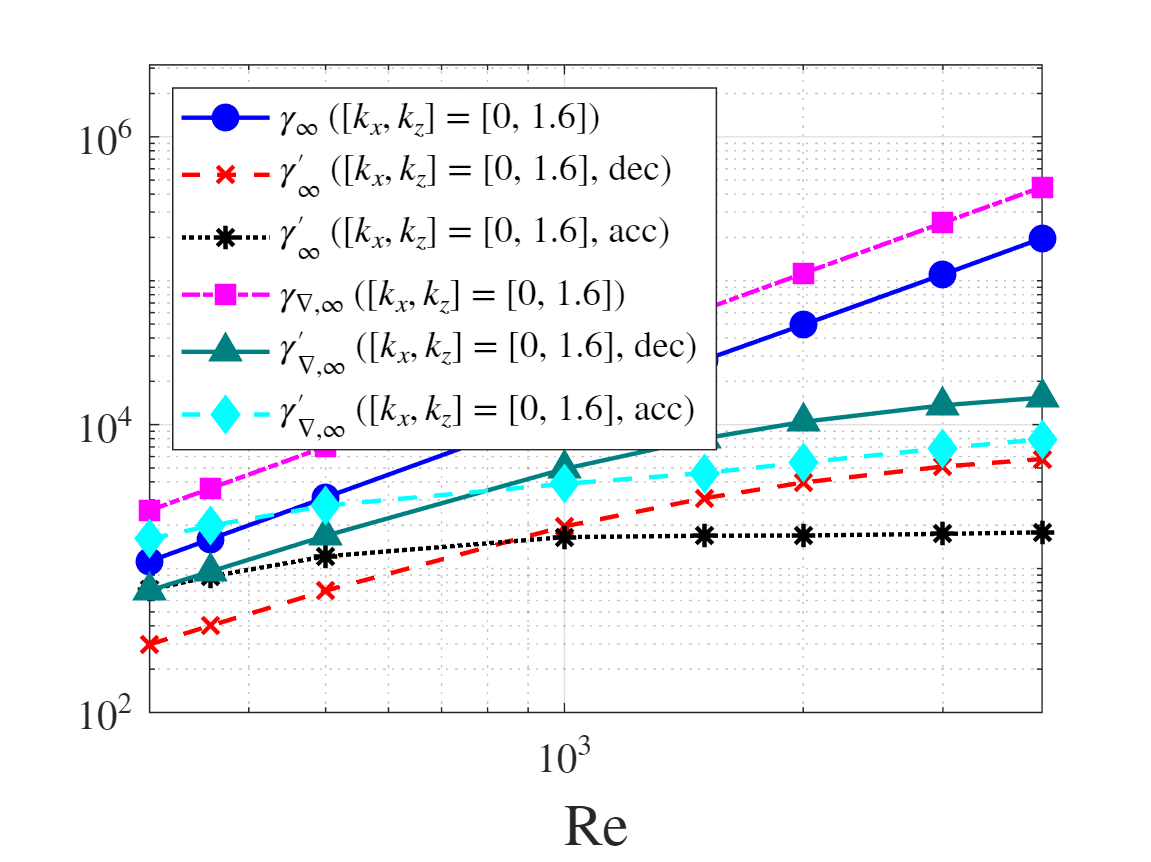

figure('Color', 'w');

% Define line properties
colors  = {'b','r','k','m',[0 0.5 0.5],'c'};
linestyles = {'-','--',':','-.','-','--'};
markers = {'o','x','*','s','^','d'};
markerFaceColors = {'b','r','k','m',[0 0.5 0.5],'c'};

% Plot each dataset
loglog(Re_list, H_infty_norm_LMI_time_independent, ...
    'Color', colors{1}, 'LineStyle', linestyles{1}, 'Marker', markers{1}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{1});
hold on;
loglog(Re_list, Time_varying_LMI_dec_H_infty_norm_kx_0_kz_1_6, ...
    'Color', colors{2}, 'LineStyle', linestyles{2}, 'Marker', markers{2}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{2});

loglog(Re_list, Time_varying_LMI_acc_H_infty_norm_kx_0_kz_1_6, ...
    'Color', colors{3}, 'LineStyle', linestyles{3}, 'Marker', markers{3}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{3});

loglog(Re_list, H_grad_infty_norm_LMI_time_independent, ...
    'Color', colors{4}, 'LineStyle', linestyles{4}, 'Marker', markers{4}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{4});

loglog(Re_list, Time_varying_LMI_dec_H_grad_infty_norm_kx_0_kz_1_6, ...
    'Color', colors{5}, 'LineStyle', linestyles{5}, 'Marker', markers{5}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{5});

loglog(Re_list, Time_varying_LMI_acc_H_grad_infty_norm_kx_0_kz_1_6, ...
    'Color', colors{6}, 'LineStyle', linestyles{6}, 'Marker', markers{6}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{6});

% loglog(Re_list, H_mussv_norm_LMI_time_independent, ...
%     'Color', colors{6}, 'LineStyle', linestyles{2}, 'Marker', markers{3}, ...
%     'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{6});

% loglog(Re_list, Time_varying_LMI_H_mussv_norm, ...
%     'Color', colors{5}, 'LineStyle', linestyles{1}, 'Marker', markers{5}, ...
%     'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{5});

% Formatting the plot
grid on;
set(gca, 'FontSize', 14, 'TickLabelInterpreter', 'latex');
xlabel('Re', 'Interpreter', 'latex', 'FontSize', 20);
xlim([300 4000]);
ylim([1e2 10^(6.5)]);

legend('$\gamma_\infty$ ($[k_x, k_z$] = [0, 1.6])', ...
       '$\gamma^{\prime}_\infty$ ($[k_x, k_z$] = [0, 1.6], dec)', ...
       '$\gamma^{\prime}_\infty$ ($[k_x, k_z$] = [0, 1.6], acc)', ...
       '$\gamma_{\nabla,\infty}$ ($[k_x, k_z$] = [0, 1.6])', ...
       '$\gamma^{\prime}_{\nabla,\infty}$ ($[k_x, k_z$] = [0, 1.6], dec)', ...
       '$\gamma^{\prime}_{\nabla,\infty}$ ($[k_x, k_z$] = [0, 1.6], acc)', ...
       'Location', 'NorthWest', 'Interpreter', 'latex');


% Legend
% legend('$\|\mathcal{H}\|_\infty$ ($k_x$ = 0, $k_z$ = 1.18)', ...
%        '$\gamma_\infty$ ($k_x$ = 0, $k_z$ = 1.18)', ...
%        '$\|\mathcal{H}_\nabla\|_\infty$ ($k_x$ = 0, $k_z$ = 1.18)', ...
%        '$\gamma_{\mu,\infty}$ ($k_x$ = 0, $k_z$ = 1.18)', ...
%        '$\|\mathcal{H}_\nabla\|_\mu$ ($k_x$ = 0.19, $k_z$ = 0.58)', ...
%        '$\gamma_\mu$ ($k_x$ = 0.19, $k_z$ = 0.58)', ...
%        'Location', 'NorthWest', 'Interpreter', 'latex');